# 'volume' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create scene

pl.scene_begin('scene_file', 'volume.pov', 'image_file', 'volume.png');
pl.global_settings("assumed_gamma 1");

pl.camera('angle', 35, 'location', [5 5 3], 'look_at', [0 0 0.5], 'type', 'orthographic');
pl.light('location', [5 5 3], 'color', [0.8 0.8 0.8]);
% pl.axis('length', [10 10 10]);

% Axis planes
% tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% 
% pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_plane_red',  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
% pl.plane('normal', [0,1,0], 'distance', 0, 'texture', tex_plane_green, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
% pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane_blue,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);

% Grid
% tex_grid_gray  = pl.declare("tex_grid_gray",  pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_grid_red   = pl.declare("tex_grid_red",   pl.texture('pigment', [1.0 0.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_grid_green = pl.declare("tex_grid_green", pl.texture('pigment', [0.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_grid_blue  = pl.declare("tex_grid_blue",  pl.texture('pigment', [0.0 0.0 1.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% 
% pl.grid('width', 10, 'height', 10, 'radius', 0.01,                     'translate', [5 0 5]);
% pl.grid('width', 10, 'height', 10, 'radius', 0.01,'rotate', [ 0 0 90], 'translate', [0 5 5]);
% pl.grid('width', 10, 'height', 10, 'radius', 0.01,'rotate', [90 0  0], 'translate', [5 5 0]);

% [x,y,z] = meshgrid([-3:0.25:3]);
% data = x.*exp(-x.^2 -y.^2 -z.^2) * 256;
% isosurface(x,y,z,data,1e-4);


#### Load data and slice data

load mri;
data = squeeze(D);
data = data(:,:,1:27);

% Check result
% histogram(data, 100)

#### Normilize data

dmax = max(data(:));
dmin = min(data(:));
drange = dmax-dmin;
data = data / drange;


#### Map colors to data

num_colors = 256;
min_step = 0.0000;
max_step = 0.0055;
scale = (min_step: (max_step-min_step) / (num_colors-1): max_step);

%color_map_type = hot(num_colors);
%color_map_type = winter(num_colors);
%color_map_type = hsv(num_colors);
color_map_type = jet(num_colors);
%color_map_type = bone(num_colors);
%color_map_type = parula(num_colors);
%color_map_type = turbo(num_colors);
%color_map_type = spring(num_colors);

color_map = [scale' color_map_type];

% Custom color map
% color_map = [0.00   0 0 0;
%              0.0001 0 0 1;
%              0.003  1 0 0;
%              0.005  0 0 1;
%              0.15   1 0 0;
%              0.20   0 0 1;
%              0.20   1 0 0;
%              0.30   0 1 0;
%              0.90   1 0 0;
%              1.00   1 0 0];


#### Call 'volume' method and close scene

pl.volume('data', data, 'density_file', 'test_vol', 'color_map', color_map, 'scale', [4 4 1], 'rotate', [ 0 0 0], 'translate', [-2 -2 0]);
pl.scene_end();

#### Render scene and show rendered image

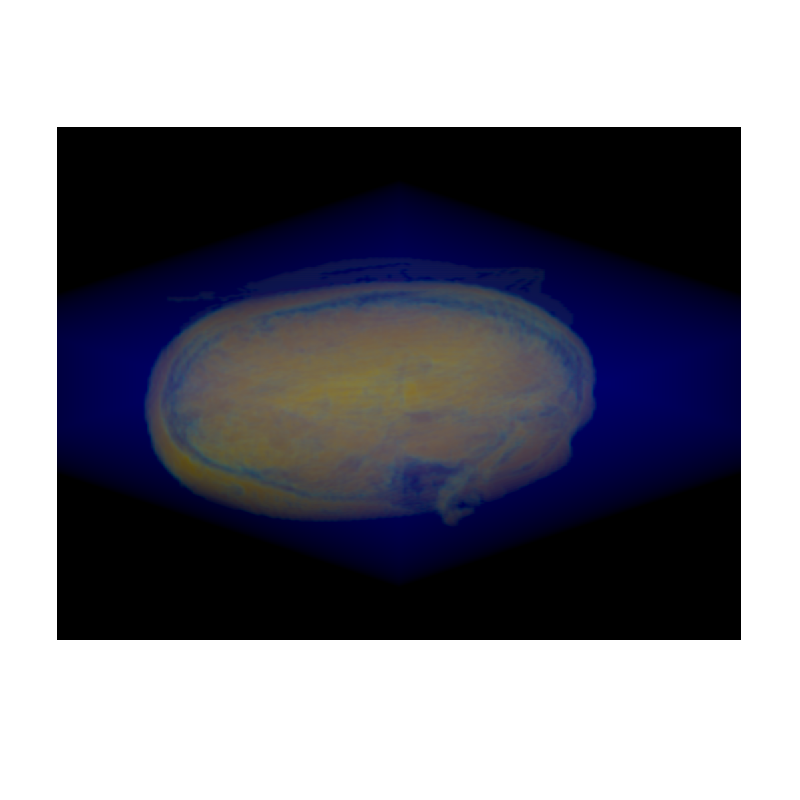

img = pl.render();
imshow(img);

#### Display elapsed time

toc

Elapsed time is 16.837423 seconds.
